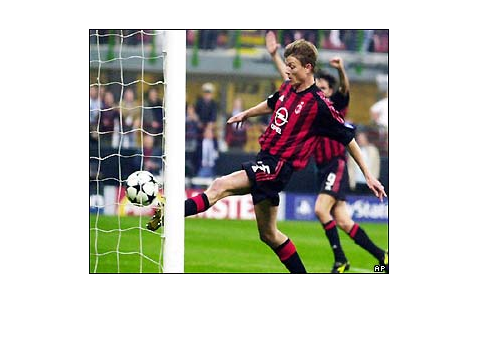

clear all
image=imread('05.jpg');
image=double(image);
figure,imshow(uint8(image))


Image_red = image(:,:,1);
Image_green = image(:,:,2);
Image_blue = image(:,:,3);

[row,col] = size(image(:,:,1));

numBlocks = 4 

numBlocks = 4

rowSize = uint32(row/numBlocks)

rowSize = uint32
61

colSize = uint32(col/numBlocks)

colSize = uint32
75


endrow = uint32(row*8)

endrow = uint32
1960

endcol = uint32(col*5)

endcol = uint32
1500

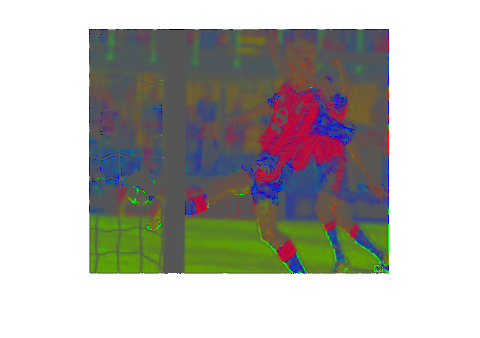


for i = 1:numBlocks
    for j= 1:numBlocks
        startrow = j*rowSize - rowSize + 1;
        startcol = i*colSize - colSize + 1;
        endrow = startrow + rowSize - 1;
        endcol = startcol + colSize - 1;
        for y = startrow:endrow 
            for x = startcol:endcol 
              Red = Image_red(y,x);
              Green = Image_green(y,x);
              Blue = Image_blue(y,x);
            
              NormalizedRed = Red/(Red + Green + Blue);
              NormalizedGreen = Green/(Red + Green + Blue);
              NormalizedBlue = Blue/(Red + Green + Blue);
            
              Image_red(y,x) = NormalizedRed;
              Image_green(y,x) = NormalizedGreen;
              Image_blue(y,x) = NormalizedBlue;
            end
        end
        
    end
end
% for y = startrow:endrow 
%     for x = startcol:endcol 
%       Red = Image_red(y,x);
%       Green = Image_green(y,x);
%       Blue = Image_blue(y,x);
%     
%       NormalizedRed = Red/(Red + Green + Blue);
%       NormalizedGreen = Green/(Red + Green + Blue);
%       NormalizedBlue = Blue/(Red + Green + Blue);
%     
%       Image_red(y,x) = NormalizedRed;
%       Image_green(y,x) = NormalizedGreen;
%       Image_blue(y,x) = NormalizedBlue;
%     end
% end
image(:,:,1) = Image_red;
image(:,:,2) = Image_green;
image(:,:,3) = Image_blue;

figure; imshow(uint8(255*image));

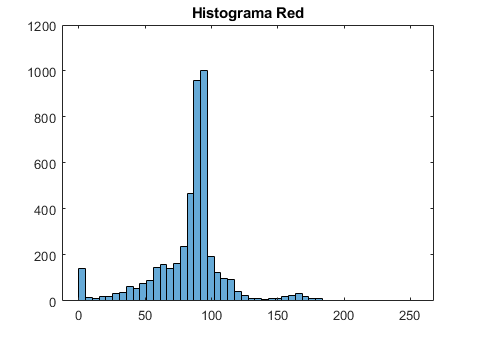


% histogram(image, nBins)
histogram(Image_red(startrow:endrow,startcol:endcol)*255, 50), title('Histograma Red')

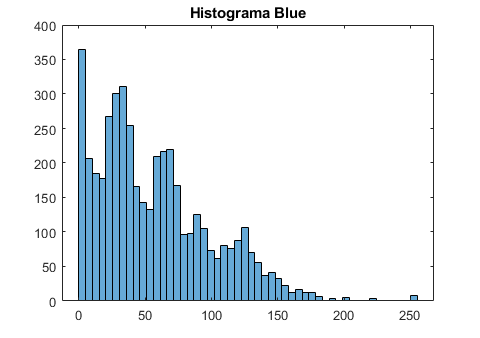

histogram(Image_blue(startrow:endrow,startcol:endcol)*255,50), title('Histograma Blue')

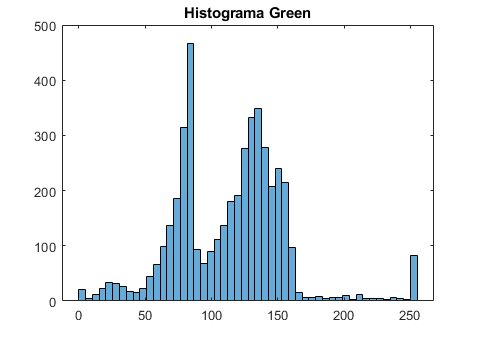

histogram(Image_green(startrow:endrow,startcol:endcol)*255,50), title('Histograma Green')